# Deep Learning Speech Recognition

In this exercise, you will train a simple deep learning model that detects the presence of speech commands in audio. 

clear

## Load Speech Commands, Data Set, and Create audioDatastore

First, we will create an audioDatastore. This will allow us to manage the large collection of audio files that will be used for training and testing the model. The audioDataStore also includes a property that allows us to automatically extract the file label information from the folder names inside the datafolder. 

*Set *`datafolder`* to the location of the dataset.*

datafolder = fullfile([filesep,'MATLAB Drive', filesep, 'Workshop', filesep, 'LargeFiles', filesep, '08-AudioFiles']);
rng('default');

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

Create a copy of the original datastore. We will extract background noise from the original datastore later on. 

ads0 = copy(ads);

## Task 1: Choose Words to Recognize

Specify which words are the commands that you want your model to recognize. Label all words that are not among the commands as `unknown`. The idea is that these words should somehow approximate the distribution of all words other than the commands. To reduce the class imbalance between the known and unknown words, only include each unknown word with a certain probability. Do not include the longer files with background noise in the `_``background_noise`_ folder.

Use [`getSubsetDatastore(ads,indices)`](matlab:edit(fullfile(matlabroot,'examples','nnet','main','getSubsetDatastore.m'))) to create a datastore that only contains the files and labels indexed by `indices`. Reduce the datastore `ads` to only contain the commands and the subset of unknown words. Count the number of examples belonging to each class.

The list of commands we will train our network on is:

- Yes

- No

- Up

- Down

- Left

- Right

- On

- Off

- Stop

- Go

`The commands should be specified in the form of a `[string array](http://web(fullfile(docroot, 'matlab/ref/string.html')))`:`

`commands = ["command1","command2",...];`

% [ADD CODE BELOW]
% commands = ["yes","no", <Finish Creating List of Commands Here> ]; 

isCommand = ismember(ads.Labels,categorical(commands));
categories(ads.Labels)
addUnknownData 
ads = getSubsetDatastore(ads,isCommand|isUnknown);
countEachLabel(ads)

## Split Data into Training, Validation, and Test Sets

Use the supporting function `splitData` to split the datastore into training, validation, and testing sets. The supporting function `splitData` will split the data with an 80-10-10 ratio. 

[adsTrain, adsValidation, adsTest] = splitData(ads,datafolder);

## Compute Speech Spectrograms

To prepare the data for efficient training of a convolutional neural network, convert the speech waveforms to log-mel auditory spectrograms. The log-mel format emphasizes frequencies that are most important in speech intelligibility. 

We will compute the spectrograms for the training, validation, and test sets by using the supporting function [`speechSpectrograms`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','speechSpectrograms.m'))). 

First, we need to define the parameters of the spectrogram calculation. 

- `segmentDuration` - duration of each audio file. In this data set, all audio files are 1 second in duration. 

- `frameDuration` - duration of each frame for spectrogram calculation. 

- `hopDuration-` time step between each column of the spectrogram. The total number of hops is equal to the width of each spectrogram.

- `numBands` - represents the height of each spectrogram (number of log-mel filters)

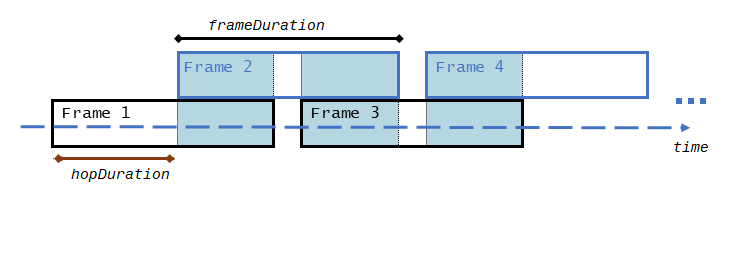

segmentDuration = 1;
frameDuration = 0.025;
hopDuration = 0.010;

Next, we can see how changing the value of the `numBands `variable affects the frequency resolution of the resulting mel spectrograms. We will apply this value to 3 randomly selected audio files from the data set and visualize the results. Remember that we are training a network to associate the spectrogram images with the spoken commands, so we want to have spectrograms that can be used to distinguish the different commands from each other.

*Try changing the numBands slider below. When the slider is changed the code below will execute. View how the spectrograms change. *

numBands = 22;

% Display 3 random spectrograms
rng('default')
adsTrainSubset = subset(shuffle(adsTrain), 1:3);
testSpectrograms = speechSpectrograms(adsTrainSubset,segmentDuration,frameDuration,hopDuration,numBands);
visualizeAndPlayClips(testSpectrograms, adsTrainSubset)

For the purposes of this example `numBands` will be set to `40.` Prior testing has found that these settings produce a good compromise between input image size and network classification accuracy. 

numBands = 40;

Now, we can create spectrograms of all of the data.  

processLive = false;
convertAllToSpectrograms

## Add Background Noise Data

The network should not only be able to recognize different spoken words. It should also be able to detect if a word is spoken at all, or if the input only contains background noise.

Use the audio files in the `_``background_noise`_ folder to create samples of one-second clips of background noise. 

Create 4000 background clips with an amplitude range between `1e-4` and 1. `XBkg` contains spectrograms of background noise with volumes ranging from practically silent to loud. By choosing these values we have a wide representation of background noises that realistically represent real-world scenarios. 

adsBkg = getSubsetDatastore(ads0, ads0.Labels=="_background_noise_");
numBkgClips = 4000;
volumeRange = [1e-4,1];

XBkg = backgroundSpectrograms(adsBkg,numBkgClips,volumeRange,segmentDuration,frameDuration,hopDuration,numBands);

Distribute the spectrograms of background noise over the training, validation, and test sets. 

splitBackgroundAudio

Plot the distribution of the different class labels in the test, training and validation sets. The training, validation, and test sets all have very similar distributions. These distributions were chosen to approximate the relative percentage of each type of word that the network might be expected to experience in a real world deployment. 

plotTrainingAndValDistrib

## Add Data Augmentation - Add some image plots 

Augmenting the data somewhat increases the variation of the training data and helps prevent the network from overfitting. The augmented image datastore creates augmented images in real time and inputs these to the network. No augmented spectrograms are saved in memory.

We utilize the XTranslation and XScale augmentations to create time shifts and pitch shifts in our audio. This results in a wider variety of speaker voices used for training. 

sz = size(XTrain);
specSize = sz(1:2);
imageSize = [specSize 1];
augmenter = imageDataAugmenter(...
    'RandXTranslation',[-10 10],...
    'RandXScale',[0.8 1.2],...
    'FillValue',log10(epsil));
augimdsTrain = augmentedImageDatastore(imageSize,XTrain,YTrain,...
    'DataAugmentation',augmenter,...
    'OutputSizeMode','randcrop');

## Define Neural Network Architecture 

Create a simple network architecture as an array of layers. Use[ convolutional](https://www.mathworks.com/help/releases/R2018b/deeplearning/ref/nnet.cnn.layer.convolution2dlayer.html) and [batch normalization](https://www.mathworks.com/help/releases/R2018b/deeplearning/ref/nnet.cnn.layer.batchnormalizationlayer.html) layers, and downsample the feature maps "spatially" (that is, in time and frequency) using [max pooling](https://www.mathworks.com/help/releases/R2018b/deeplearning/ref/nnet.cnn.layer.maxpooling2dlayer.html) layers. Add a final max pooling layer that pools the input feature map globally over time. 

To reduce the chance of the network memorizing specific features of the training data, add a small amount of dropout to the inputs to the layers with the largest number of parameters. These layers are the convolutional layers with the largest number of filters. 

Use a weighted cross entropy classification loss. [`weightedCrossEntropyLayer(classNames,classWeights)`](matlab:edit(fullfile(matlabroot,'examples','nnet','main','weightedCrossEntropyLayer.m'))) creates a custom layer that calculates the weighted cross entropy loss for the classes in `classNames` using the weights in `classWeights`. To give each class equal weight in the loss, use class weights that are inversely proportional to the number of training examples of each class. When using the Adam optimizer to train the network, training should be independent of the overall normalization of the class weights.

classNames = categories(YTrain);
classWeights = 1./countcats(YTrain);
classWeights = classWeights/mean(classWeights);
numClasses = numel(classNames);

dropoutProb = 0.2;
layers = [
    imageInputLayer(imageSize)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2,'Padding',[0,1])
    
    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2,'Padding',[0,1])
    
    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer([1 13])
    fullyConnectedLayer(numClasses)
    
    softmaxLayer
    weightedCrossEntropyLayer(classNames,classWeights)];

% deepNetworkDesigner

## Task 2: Set Training Options

*Add in the following name-value pairs to the training options:*

- *Mini-batch size: 128*

- *Initial Learn Rate: 5e-4*

- *Max Epochs: 5*

miniBatchSize = 128;
validationFrequency = floor(numel(YTrain)/miniBatchSize);


options = trainingOptions('adam', ... %add name value pairs below
    ...
    ...
    ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',3);

## Task 3: Train the Network

Train the network using the conmand below. If you do not have a GPU, then training the network can take some time. To load the pretrained network instead of training a network from scratch, run the commented code.

% [ADD CODE HERE]
    
% s = load('commandNet.mat');
% trainedNet = s.trainedNet;

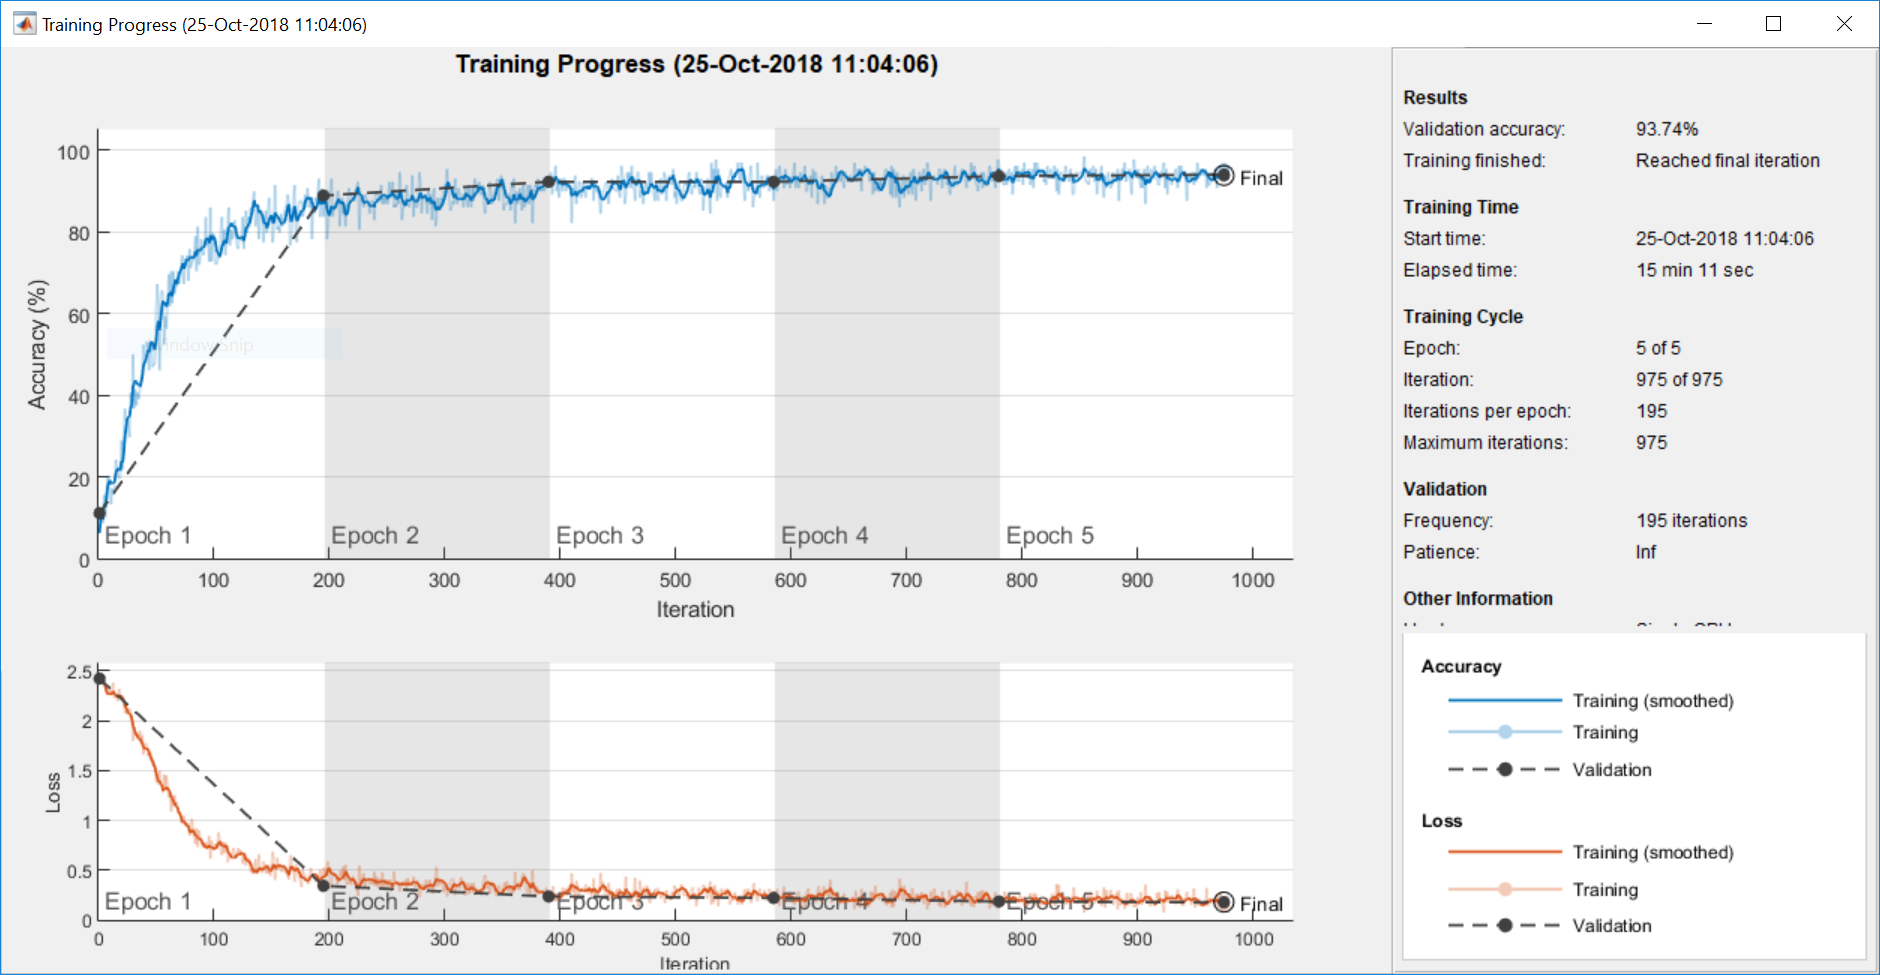

## Task 4: Evaluate Trained Network

Calculate the final accuracy on the training set (without data augmentation) and validation set. Plot the confusion matrix. The network is very accurate on this data set. However, the training, validation, and test data all come from similar distributions that do not necessarily reflect real-world environments. This applies in particular to the `unknown` category which contains utterances of a small number of words only.

*Call the *[classify method of the trained network](http://web(fullfile(docroot, 'deeplearning/ref/classify.html')))* in order to validate it. *

*The input is the variable XValidation and store the output results in variable YValPred:*

% [ADD CODE BELOW]
% YValPred = classify();

validationError = mean(YValPred ~= YValidation);

YTestPred = classify(trainedNet,XTest);
testError = mean(YTestPred ~= YTest);

disp("Validation error: " + validationError*100 + "%")
disp("Test error: " + testError*100 + "%")
clf
confusionchart(YTest,YTestPred,'Title','Test Data');

## Summary

One common practice for classifying audio signals is to convert them to speech spectrograms, which can be used to train a CNN. The other approach to signal problems is to use an LSTM. For more information and examples, please visit the documentation.